clc; clear all; close all

## **Task A1: recreation of fig 6.4 in the textbook**

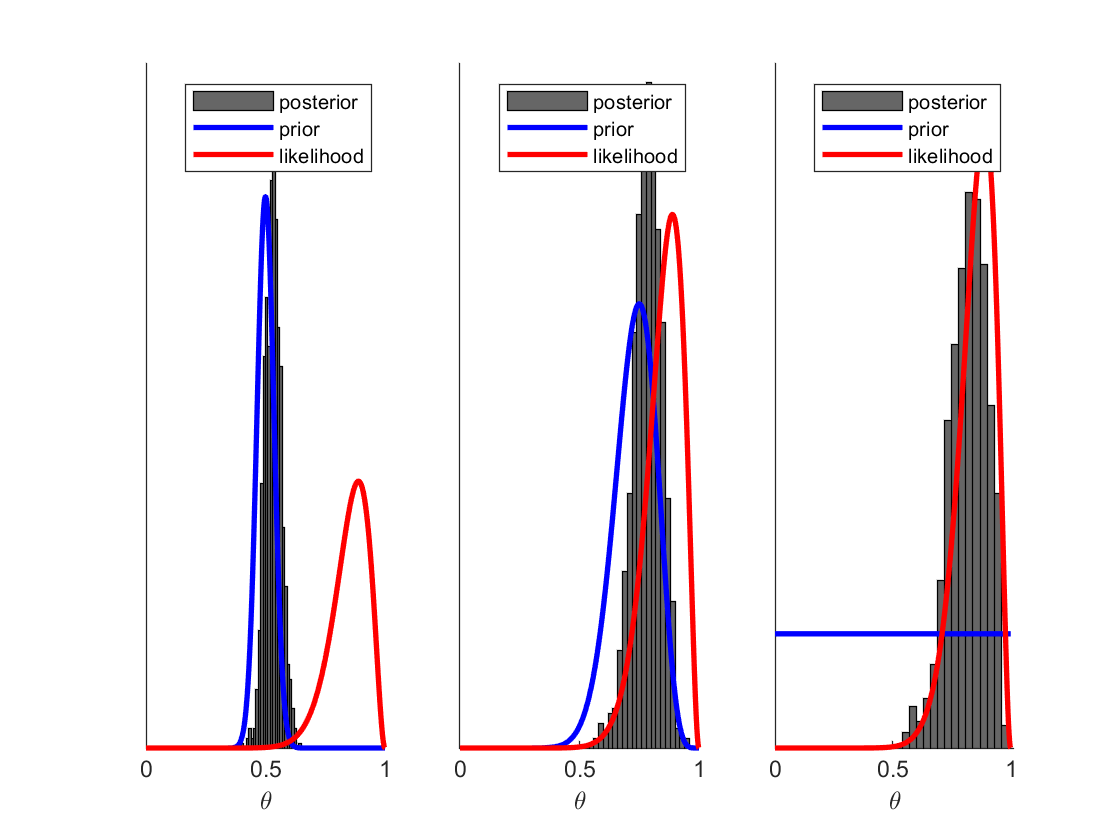

tet0 = 0.5;   % initial
Ns = 1000;    % Number of samples

y = [ones(17,1);zeros(3,1)];
a = [100 18.25 1];
b = [100 6.75 1];

tet = linspace(0,1,1e3);

figure;
for i = 1 : length(a)
    
    rnd = slicesample(tet0,Ns,'logpdf',@(tet) Log_Posterior_PDF(y,tet,a(i),b(i)));
    
    beta_prior = (tet.^(a(i)-1).*(1-tet).^(b(i)-1))/trapz(tet,tet.^(a(i)-1).*(1-tet).^(b(i)-1));
    beta_likelihood = (tet.^(sum(y)-1).*(1-tet).^(length(y)-sum(y)-1))/trapz(tet,tet.^(sum(y)-1).*(1-tet).^(length(y)-sum(y)-1));
    
    subplot(1,3,i);hold on
    histogram(rnd,'normalization','pdf','edgecolor','k','facecolor','k');
    plot(tet,beta_prior,'b',tet,beta_likelihood,'r','linewidth',2)
    
    set(gca,'ytick',[]);
    legend('posterior','prior','likelihood')
    xlabel('\theta')
    
end

### **Task A.2: Once you get things running with the example code and you manage to recreate Figure 6.4, answer the following questions: **

A2a. Given the following measurements y = [1 0 1 1 0 1 1 1 0 1 1 1 1];

i. What is the expected probability of getting a head?

Give a 95% credible interval of this probability ** asnwer: around 0.75**

ii. What is the probability that >0.5?    answer:**  around 0.97.4**

A2b. Given an additional set of measurements , z = [1 0 0 0 0 0 0 1 1 0]; 

are  and  measurements from the same coin? You may answer this in different ways

- Answer this by callating the probability that $\theta_y >\theta_z$  given the measurements y,z. **answer: 98%**

- Answer this by creating a new variable $d\theta =\theta_{y\;} -\theta_z$ and calculating a 95% credible interval.  **answer: No, since** confidence interval is 0.06-0.73 which does NOT include 0

- Plot a histogram representing $p\left(d\theta |y,z\right)$. Is it beta distributed? Motivate your answer. **a****nswer: No since it containes negative values.**

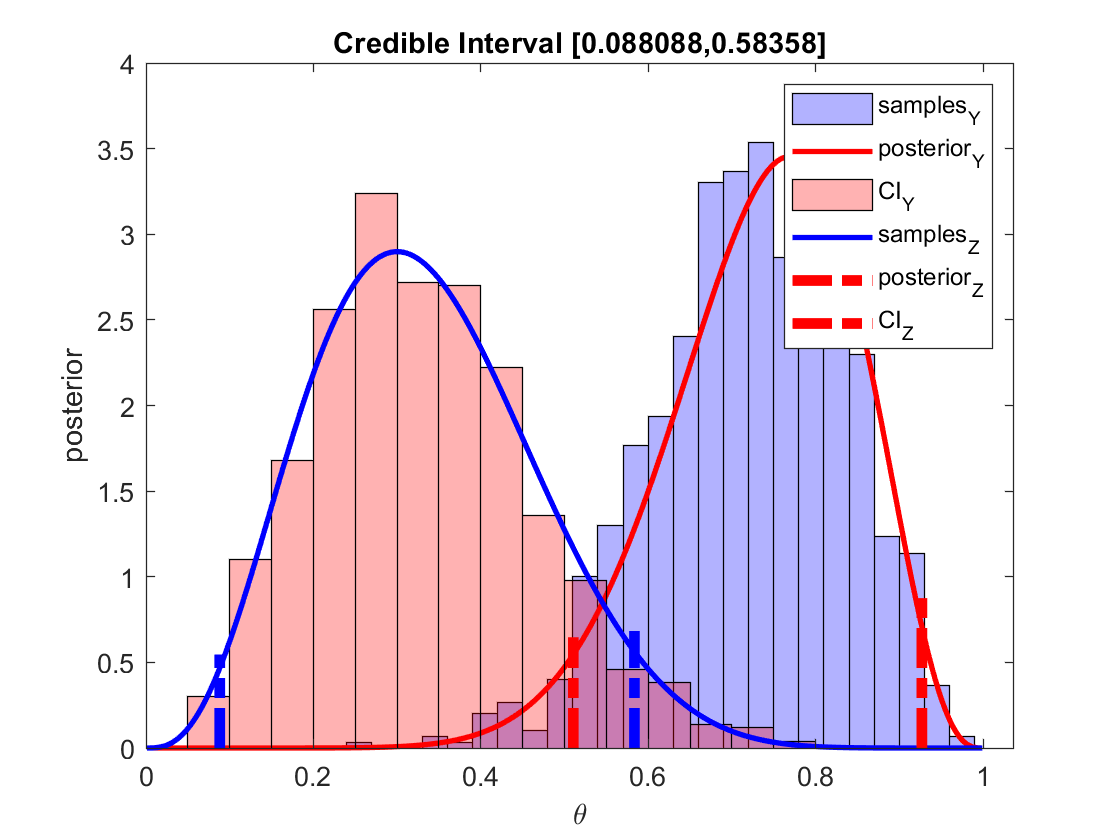

clc
clear all
y = [1 0 1 1 0 1 1 1 0 1 1 1 1];

a = 1;
b = 1;
tet0 = 0.5;
Ns = 1e3;
ry = @(tet) Log_Posterior_PDF(y,tet,a,b);
y_rnd = slicesample(tet0,Ns,'logpdf',ry);

z = [1 0 0 0 0 0 0 1 1 0];
rz = @(tet) Log_Posterior_PDF(z,tet,a,b);
z_rnd = slicesample(tet0,Ns,'logpdf',rz);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure(2)
hy = histogram(y_rnd,'normalization','pdf');hold on
% [binheight,bincenter] = hist(y_rnd,32);
% h = bar(bincenter,binheight,'hist'); hold on
hy.FaceAlpha = 0.3;
hy.FaceColor = [0 0 1];

tet = linspace(0,1,1e3);
tet = tet(2:end-1); % excluding 0 and 1 from span

for i = 1:length(tet)
    Ry(i) = exp(ry(tet(i)));
end
areay = trapz(log(Ry),tet);
% hy.binwidth = (hy.bincenter(2)-hy.bincenter(1));
YR = (Ns^2*hy.BinWidth/abs(areay))* Ry;
plot(tet,YR,'r','LineWidth',2)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

p_ci_yz0=sum(y_rnd> z_rnd)/Ns;
hz = histogram(z_rnd,'normalization','pdf');hold on
% [binheight,bincenter] = hist(y_rnd,32);
% h = bar(bincenter,binheight,'hist'); hold on
hz.FaceAlpha = 0.3;
hz.FaceColor = [1 0 0];

for i = 1:length(tet)
    Rz(i) = exp(rz(tet(i)));
end
areaz = trapz(log(Rz),tet);
% hy.binwidth = (hy.bincenter(2)-hy.bincenter(1));
ZR = (Ns^2*hz.BinWidth/abs(areaz))* Rz;
plot(tet,ZR,'b','LineWidth',2)

ci = HDI(tet,Ry,0.95);

plot(ci(1)*[1 1],[0 1.2*YR(floor(ci(1)*length(tet)))],'r','linewidth',4,'Linestyle','-.')
plot(ci(2)*[1 1],[0 1.2*YR(floor(ci(2)*length(tet)))],'r','linewidth',4,'Linestyle','-.')

ci = HDI(tet,Rz,0.95);
plot(ci(1)*[1 1],[0 1.2*ZR(floor(ci(1)*length(tet)))],'b','linewidth',4,'Linestyle','-.')
plot(ci(2)*[1 1],[0 1.2*ZR(floor(ci(2)*length(tet)))],'b','linewidth',4,'Linestyle','-.')

title(['Credible Interval [',num2str(ci(1)),',',num2str(ci(2)),']'])
xlabel('\theta')
ylabel('posterior')
legend('samples_Y','posterior_Y','CI_Y','samples_Z','posterior_Z','CI_Z')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
py_tet05 = sum(y_rnd>0.5)/Ns;

fprintf('\nproblem 2a)\n')


problem 2a)


fprintf('i. tet_y with 95%% likelihood in [%f,%f]\n',ci(1),ci(2))

i. tet_y with 95% likelihood in [0.088088,0.583584]


fprintf('ii. %f%% chance that tet is larger than 0.5 given y\n',py_tet05*100)

ii. 97.400000% chance that tet is larger than 0.5 given y


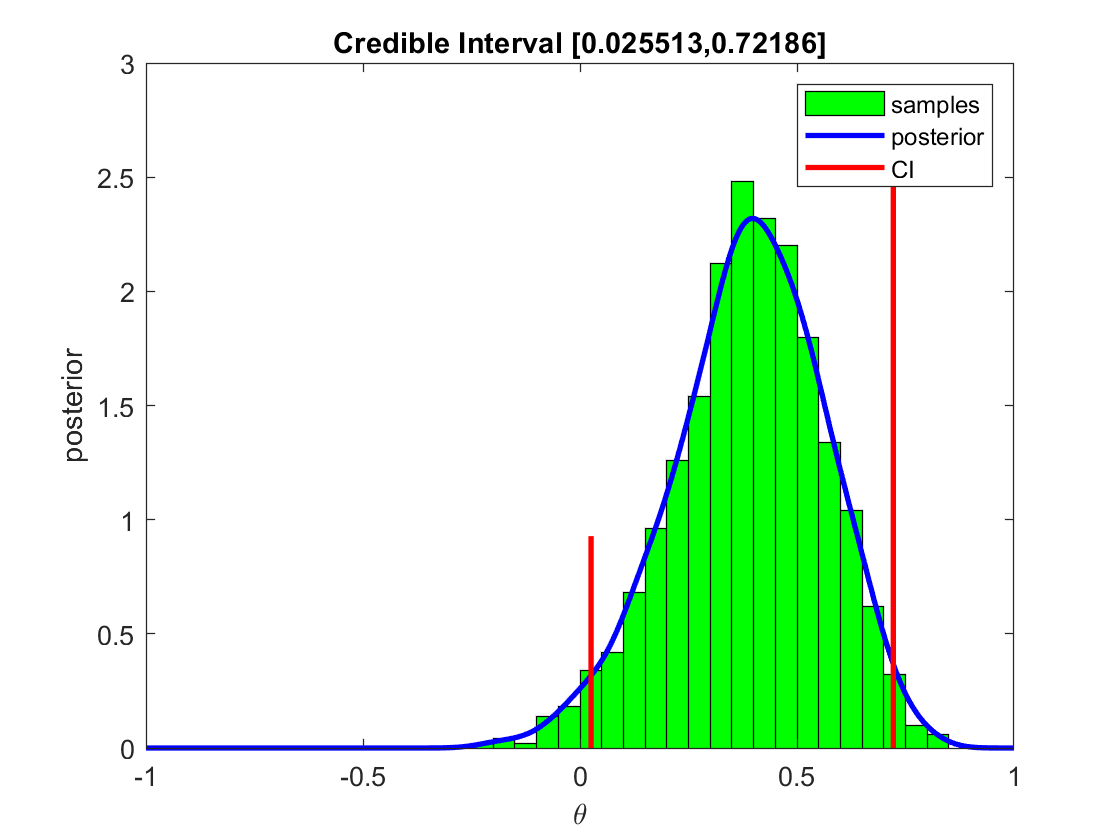

ci_yz = linspace(-1,1,length(tet));
rnd_yz = y_rnd - z_rnd;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dtet = linspace(-1,1,2e3);
rnd_yz = y_rnd-z_rnd;
pd_yz = fitdist(rnd_yz,'kernel');
fit_yz = pdf(pd_yz,dtet);
ci_yz = HDI(dtet,fit_yz,0.95);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
hyz = histogram(rnd_yz,'normalization','pdf');hold on

hyz.FaceAlpha = 1;
hyz.FaceColor = [0 1 0];

plot(dtet,fit_yz,'b','linewidth',2)
plot(ci_yz(1)*[1 1],[0 0.4*max(fit_yz)],'r','linewidth',2)
plot(ci_yz(2)*[1 1],[0 1.2*fit_yz(floor(ci_yz(2)*length(dtet)))],'r','linewidth',2)

title(['Credible Interval [',num2str(ci_yz(1)),',',num2str(ci_yz(2)),']'])
xlabel('\theta')
ylabel('posterior')
legend('samples','posterior','CI')


fprintf('\nproblem 2b)\n')


problem 2b)


fprintf('1. %f%% chance that tet_y is larger than tet_z given y\n',p_ci_yz0*100)

1. 98.000000% chance that tet_y is larger than tet_z given y


fprintf('2. tet_y - tet_z with 95%% likelihood lies in [%f,%f]\n',ci_yz(1),ci_yz(2))

2. tet_y - tet_z with 95% likelihood in [0.025513,0.721861]


fprintf('3. tet_y - tet_z lies in [-1,1], while beta is defined on [0,1]\n')

3. tet_y - tet_z could assume values in [-1,1], beta is defined on [0,1]


## used functions

function r = Log_Posterior_PDF(y,tet,a,b)

Log_Bern_PDF = @(y,tet) log(tet).*y + log(1-tet).*(1-y);

Log_likly = @(y,tet) sum(Log_Bern_PDF(y,tet));

log_B=@(a,b) gammaln(a) + gammaln(b) - gammaln(a+b);
Log_BetaPrior_PDF = @(tet,a,b) (a-1).*log(tet)+(b-1).*log(1-tet)-log_B(a,b);

if isreal(Log_likly(y,tet)) %check if tet is out of range
    r = Log_likly(y,tet) + Log_BetaPrior_PDF(tet,a,b);
else
    r = -inf;
end
end

function ci = HDI(x,y,alpha)
I0 = trapz(x,y);
I=0;
k = 1;
while k < length(x)
    p =k+1;
    while I < alpha*I0 && p < length(x)
        I = trapz(x(k:p),y(k:p));
        p=p+1;
    end
    if I > alpha*I0
        L(k) = x(p-1)-x(k);
        cii(1,k) = x(k);
        cii(2,k) = x(p-1);
    else L(k) = inf;
    end
    I = 0;
    k = k+1;
end
[M,I] =  min(L);
ci(1) = cii(1,I);
ci(2) = ci(1) + min(L);

end